# Feedforward neural network

BE CAREFUL, THIS SCRIPT CAN OVERWRITE FILES

buffer = 1.0e+05 *

    4.2279    4.2247    4.2248    4.2308    4.2291    4.2297    4.2282    4.2206    4.2223    4.2199    4.2208    4.2290    4.2253    4.2375    4.2298    4.2240    4.2224    4.2246    4.2223    4.2169    4.2289    4.2274    4.2241    4.2297    4.2247    4.2248    4.2228    4.2298    4.2264    4.2262    4.2133    4.2251    4.2251    4.2283    4.2247    4.2205    4.2241    4.2226    4.2296    4.2278    4.2251    4.2242    4.2207    4.2255    4.2260    4.2188    4.2276    4.2241    4.2258    4.2303
    0.0108    0.0139    0.0035    0.0105    0.0029   -0.0090   -0.0189    0.0007    0.0001    0.0011   -0.0055    0.0122   -0.0004    0.0029   -0.0023   -0.0034    0.0169    0.0158   -0.0103    0.0005   -0.0107   -0.0045    0.0107    0.0051   -0.0078   -0.0076   -0.0017   -0.0047    0.0070   -0.0054   -0.0007   -0.0052    0.0164   -0.0051   -0.0090    0.0010   -0.0008   -0.0136   -0.0180    0.0097   -0.0072    0.0156    0.0079    0.0161    0.0150   -0.0086    0.0136    0.010

Nbuffer_variables = 28

Nsamples = 101000

Ninputs = 22

Noutputs = 5

ans =           22      101000


ans =            5      101000


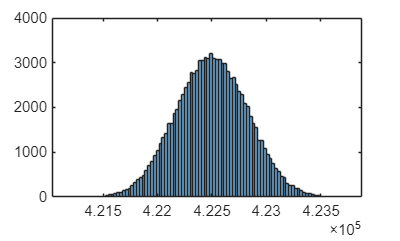

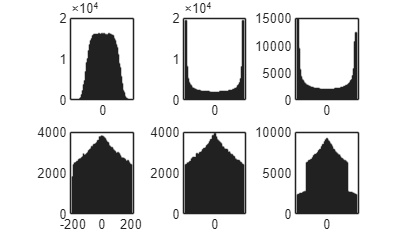

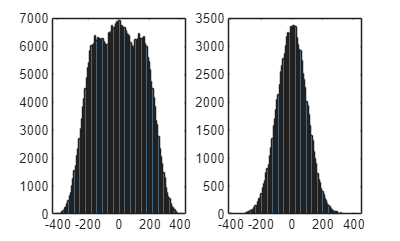

ans = 159.8981

ie_max = 398.6229

ix_max = 200

iy_max = 280

is_max = 250

vo_max = 1000

vB_max = 12000

C = 0.0050

vc_mean_ref = 13000

Xmax = 1.0e+05 *

    4.6475
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0770
    0.0770
    0.0770
    0.0550
    0.0550


Ymax =          500
         500
         500
         500
        1000


Ninputs = 22

Nsamples = 101000

Noutputs = 5

Nsamples = 101000

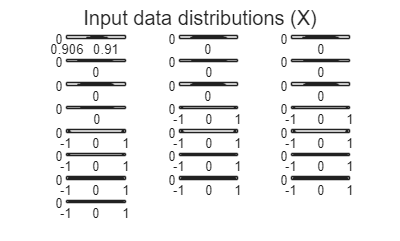

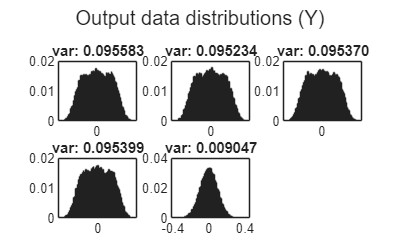

run('DataPreparation.mlx');

save_net = true; % Overwrite current feedforward architecture

## Architecture

argsFFNN                  = struct();
argsFFNN.Ninputs          = Ninputs;
argsFFNN.Noutputs         = Noutputs;
argsFFNN.Nlayers          = 1;
argsFFNN.Nneurons         = 3*Ninputs;
argsFFNN.HiddenActivation = 'relu';
argsFFNN.OutputActivation = 'tanh';
argsFFNN.Dropout          = 0;
argsFFNN.WinitFcn         = 'glorot';
argsFFNN.BinitFcn         = 'glorot';
argsFFNN.BatchNorm        = true;
argsFFNN.TrainBias        = true;

FFnet = FFNNgenerator(argsFFNN)

FFnet =   dlnetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'tanh'}
    Initialized: 1

  View summary with summary.


## Training

output_variance = var(extractdata(dlY_tr), 0, 2);
var_e = mean(output_variance(1:4));
var_o = output_variance(5);
ErrorWeights = [ones(4, 1); var_e/var_o]

ErrorWeights =     1.0000
    1.0000
    1.0000
    1.0000
   10.5437



argsFFNNtrain                     = struct();
argsFFNNtrain.net                 = FFnet;
argsFFNNtrain.X_tr                = dlX_tr;
argsFFNNtrain.Y_tr                = dlY_tr;
argsFFNNtrain.X_val               = dlX_val;
argsFFNNtrain.Y_val               = dlY_val;
argsFFNNtrain.InitialLearningRate = 1e-2;
argsFFNNtrain.FinalLearningRate   = 1e-6;
argsFFNNtrain.Plots               = 'training-progress'

argsFFNNtrain = struct with fields:
                    net: [1×1 dlnetwork]
                   X_tr: [22×100000 dlarray]
                   Y_tr: [5×100000 dlarray]
                  X_val: [22×1000 dlarray]
                  Y_val: [5×1000 dlarray]
    InitialLearningRate: 0.0100
      FinalLearningRate: 1.0000e-06
                  Plots: 'training-progress'


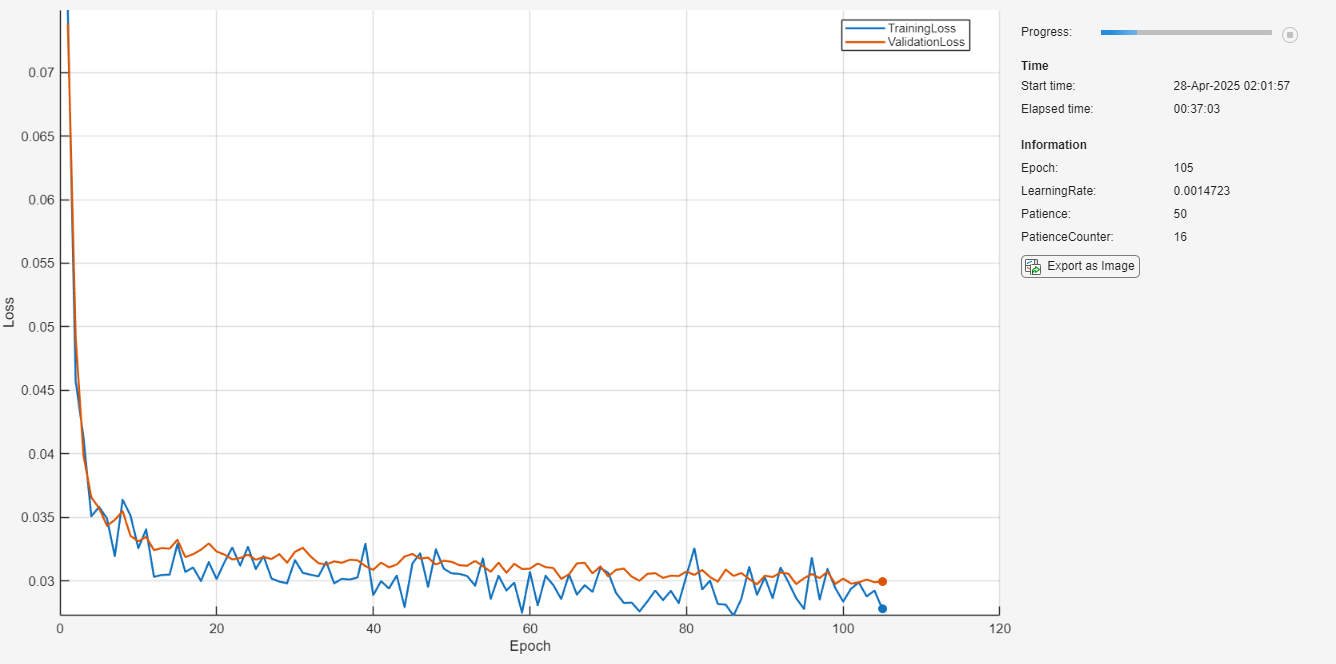

Manual training stopping at epoch 106.


FFnet =   dlnetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'tanh'}
    Initialized: 1

  View summary with summary.


argsFFNNtrain.Verbose             = false;
argsFFNNtrain.MaxEpochs           = 500;
argsFFNNtrain.MiniBatchSize       = 128; % This could be adaptive during training for better fitting and generalization
argsFFNNtrain.ValidationPatience  = 50;
argsFFNNtrain.HuberThreshold      = 1;
argsFFNNtrain.ErrorWeights        = ErrorWeights;

FFnet = FFNNtrain(argsFFNNtrain, 'custom')


if save_net
    save('ImitationLearning\ActualArchitecture\FFnet.mat', "FFnet")
end

Error using save
Cannot create 'FFnet.mat' because 'ImitationLearning\ActualArchitecture' does not exist.

figure
subplot(2, 2, 1)
histogram(FFnet.Layers(3).Offset)
title('Offset')
subplot(2, 2, 2)
histogram(FFnet.Layers(3).Scale)
title('Scale')
subplot(2, 2, 3)
histogram(FFnet.Layers(3).TrainedMean)
title('TrainedMean')
subplot(2, 2, 4)
histogram(FFnet.Layers(3).TrainedVariance)
title('TrainedVariance')
sgtitle('BatchNormLayer')

## Summary

trainPerformance = dlfeval(@FFNNLoss, FFnet, dlX_tr, dlY_tr, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);
valPerformance   = dlfeval(@FFNNLoss, FFnet, dlX_val, dlY_val, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);

disp(['Rendimiento en el conjunto de entrenamiento: ', num2str(trainPerformance)]);
disp(['Rendimiento en el conjunto de validación: ', num2str(valPerformance)]);

figure
plot(FFnet)
analyzeNetwork(FFnet);
summary(FFnet)

# Performance analysis

## Complete timeseries

% pred = extractdata(FFnet.predict(dlX));
% figure
% subplot(ceil(Noutputs/3), 3, 1)
% stairs(1:Nsamples, Y(1, :))
% hold on
% stairs(1:Nsamples, pred(1, :))
% hold off
% for idx = 2:Noutputs
%     subplot(ceil(Noutputs/3), 3, idx)
%     stairs(1:Nsamples, Y(idx, :))
%     hold on
%     stairs(1:Nsamples, pred(idx, :))
%     hold off
% end
% sgtitle('Complete timeseries');

## Error histogram

Y_tr_pred = extractdata(FFnet.predict(dlX_tr));
Y_val_pred = extractdata(FFnet.predict(dlX_val));

figure
subplot(1, 2, 1)
histogram(mean((Y_tr_pred - Y_tr).^2, 2), 1000, 'Normalization', 'probability')
title("Training")
xlabel("Error");
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Y_val_pred - Y_val).^2, 2), 1000, 'Normalization', 'probability')
title("Validation")
xlabel("Error");
ylabel("Frequency")

sgtitle('Error histogram');

## Regression

% xlabel("Predicted")
% ylabel("Actual")
% title("Correlation")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_tr_pred(1, :), Y_tr(1, :), "+")
title(corr(Y_tr_pred(1, :)', Y_tr(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_tr_pred(idx, :), Y_tr(idx, :), "+")
    title(corr(Y_tr_pred(idx, :)', Y_tr(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_val_pred(1, :), Y_val(1, :), "+")
title(corr(Y_val_pred(1, :)', Y_val(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_val_pred(idx, :), Y_val(idx, :), "+")
    title(corr(Y_val_pred(idx, :)', Y_val(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

Learnables = FFnet.Learnables
Learnables = Learnables.Value;

weights_input_hidden = extractdata(Learnables{1});

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Weights');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

Near zero weights

weights_treshold = 0.01 * max(abs(weights_input_hidden(:)))
weights_input_hidden(abs(weights_input_hidden) <= weights_treshold) = 0;
weights_input_hidden(abs(weights_input_hidden) > weights_treshold) = 1;

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Absolute weights near zero');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));